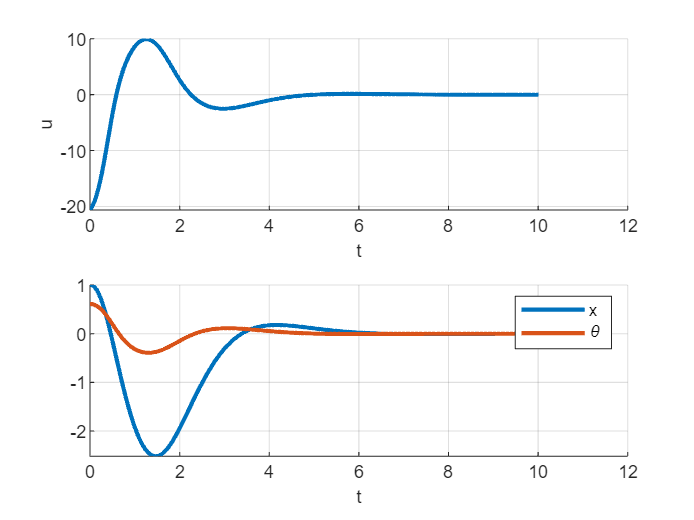

%% 仿真初始设置
close all,clear,clc,
tic,

global m1 m2 l g
m1 = 1;
m2 = 1;
l = 1;
g = 9.8;

x = 1;
theta = deg2rad(35);
v = 0.2;
omega = deg2rad(2);

z = [x;theta;v;omega];
zout = z;

t0 = 0.0;
dt = 0.01;
tf = 10;
tout = t0:dt:tf;
uout = [];
% place直接求增益
A = [0 0 1 0; 0 0 0 1; 0 m2*g/m1 0 0; 0 (m1+m2)*g/m1/l 0 0];
B = [0; 0; 1/m1; 1/m1/l];
lambda = [-1+i; -1-i; -2+i; -2-i];
K = place(A, B, lambda);  % 状态反馈增益矩阵
%% 仿真
for t = t0:dt:tf
    u = -K*z;
    uout = [uout,u];

    ke1 = stateequation(t, z, u);
    ke2 = stateequation(t+0.5*dt, z+0.5*ke1*dt, u);
    ke3 = stateequation(t+0.5*dt, z+0.5*ke2*dt, u);
    ke4 = stateequation(t+dt, z+ke3*dt, u);
    z = z + 1/6*(ke1 + 2*ke2 + 2*ke3 + ke4)*dt;
    zout = [zout, z];

    x = z(1);
    theta = z(2);
    v = z(3);
    omega = z(4);
end

xout = zout(1, :);
thetaout = zout(2, :);
vout = zout(3, :);
omegaout = zout(4, :);

uout = [uout,uout(end)];
tout = [tout,tout(end)+dt];

%% 绘图 
figure;
subplot(2, 1, 1);
hold on;grid on;
plot(tout, uout, 'LineWidth', 2);
xlabel('t');ylabel('u');

subplot(2, 1, 2);
hold on;grid on;
plot(tout, xout, 'LineWidth', 2);
plot(tout, thetaout, 'LineWidth', 2);
xlabel('t');
legend("x","\theta");

%% 函数

function zdot=stateequation(t, z, u)
global m1 m2 l g

x = z(1);
theta = z(2);
v = z(3);
omega = z(4);

A = [m1 + m2, -m2*l*cos(theta); -m2*l*cos(theta), m2*l^2];
B = [-m2*l*omega^2*sin(theta) + u; m2*l*g*sin(theta)];

xdot = v;
thetadot = omega;
dotdot = inv(A)*B;
vdot = dotdot(1);
omegadot = dotdot(2);

zdot = [xdot;thetadot;vdot;omegadot];
end